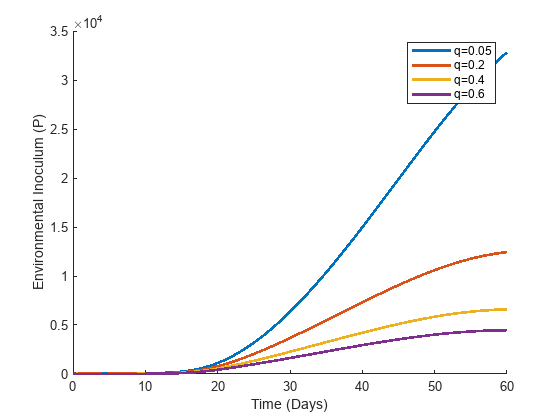

clc;
clear;
close all;

%% TIME
tspan = [0 60];

%% INITIAL CONDITIONS
X0 = [200 100 50 0 10 20];

%% κ VALUES (Scenario 4)
kappa_values = [0.05, 0.2, 0.4, 0.6];

colors = lines(length(kappa_values));

figure; hold on;

for j = 1:length(kappa_values)

    kappa = kappa_values(j);

    %% SOLVE ODE
    [t,X] = ode45(@(t,X) model(t,X,kappa), tspan, X0);

    P = X(:,6);   % ONLY environmental inoculum

    plot(t, P, 'LineWidth', 2, 'Color', colors(j,:));
end

xlabel('Time (Days)');
ylabel('Environmental Inoculum (P)');
legend('q=0.05','q=0.2','q=0.4','q=0.6');



%% ================= MODEL =================
function dX = model(t,X,kappa)

S = X(1); E = X(2); I = X(3);
R = X(4); C = X(5); P = X(6);

%% PARAMETERS
Lambda = 20000;
mu = 0.015;

betaP0 = 0.012;
betaC0 = 0.0015;

sigma = 0.005;
eta = 0.01;

gammaMax = 0.75;

psi = 0.0303;
h = 0.018;

delta = 0.18;

theta = 0.06;
muP = 0.015;

v = 0;

%% CLIMATE
T = 25 + 2*sin(2*pi*t/120);
Rain = 20 + 5*sin(2*pi*t/120);
H = 0.85 + 0.05*sin(2*pi*t/120);
M = 0.5 + 0.1*sin(2*pi*t/120);

%% RESPONSE FUNCTIONS
fT = exp(-((T-25)^2)/(2*5^2));
fR = (1-exp(-0.3*max(0,Rain))) * exp(-((Rain-20)^2)/(2*10^2));
fH = 1/(1+exp(-30*(H-0.9)));
fM = min(1, M/0.6);

%% RATES
gamma_t = gammaMax*fT*fH*fR;
omega_t = 0.01*fT*fH*fR;

betaP = betaP0*fM;
betaC = betaC0*fR*fH;

d = 1;
lambda = betaP*(P/(d+P)) + betaC*C;

%% SYSTEM
dS = Lambda - lambda*S - mu*S;
dE = lambda*S - (omega_t + mu)*E;
dI = omega_t*E - (sigma + mu + v + eta)*I;
dR = (v + eta)*I - mu*R;

dC = gamma_t*I + psi*(P/(h+P)) - delta*C;

%% KEY SCENARIO 4 EFFECT
dP = theta*I - (muP + kappa)*P;

dX = [dS; dE; dI; dR; dC; dP];

end